푸리에 급수

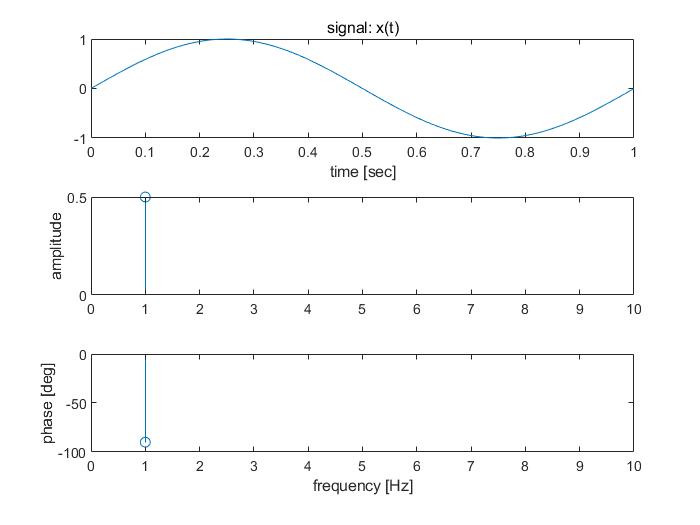

f = 1; % Hz
t = 0:0.01:1;
x = sin(2*pi*f*t);
figure
[freq,amp,phase,dc] = fourier_series_real(t,x);
subplot(3,1,1); plot(t,x);
xlabel('time [sec]');
title('signal: x(t)');
subplot(3,1,2); stem(amp);
xlim([0 10]);
ylabel('amplitude');
subplot(3,1,3); stem(phase*180/pi);
xlim([0 10]);
ylabel('phase [deg]');
xlabel('frequency [Hz]');

주기신호의 푸리에 급수

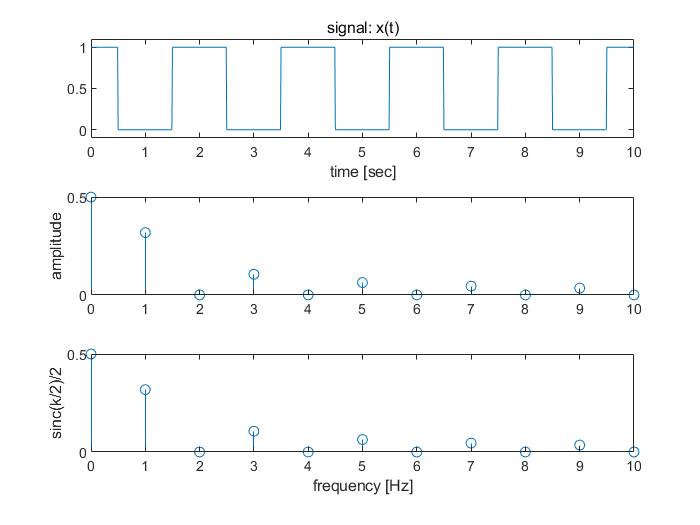

T=2; dt=0.01;
x=[ones(1,0.5/dt) zeros(1,1/dt) ones(1,0.5/dt)];
figure
xp=[x x x x x];
k1=0:dt:(length(xp)-1)*dt;
[freq,amp,phase,dc] = fourier_series_real(k1,xp);
subplot(3,1,1); plot(k1,xp);
axis([0 T*5 -0.1 1.1]);
xlabel('time [sec]');
title('signal: x(t)');
amp1=[dc,amp];
amp2=amp1(1:5:length(amp1));
k2=0:length(amp2)-1;
subplot(3,1,2); stem(k2,amp2);
axis([0 10 0 0.5]);
ylabel('amplitude');
k3=0:length(freq)-1;
subplot(3,1,3); stem(k3,abs(sinc(k3/2)/2));
ylabel('sinc(k/2)/2');
xlabel('frequency [Hz]');
axis([0 10 0 0.5]);

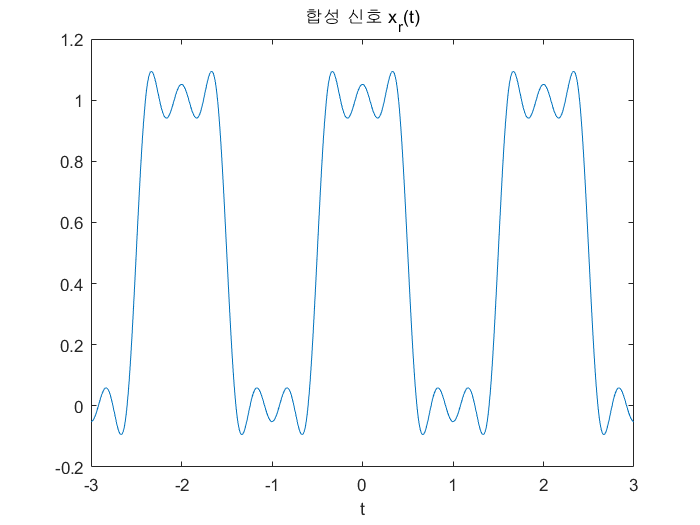

t=-3:0.01:3;
X0=0.5; % 직류 성분의 Fourier 계수
figure
for steps=1:1:5
    xr1=X0*ones(1,length(t)); % 합성 신호 의 직류 성분
    for k=1:steps
        Xk1=sinc(k/2)/2; % Fourier series coefficients
        xr1=xr1+Xk1*(exp(j*k*pi*t)+exp(-j*k*pi*t));
    end
    plot(t,xr1) % 합성 신호 의 파형을 그림
    title('합성 신호 x_r(t)'); % 그림 제목
    xlabel('t'); % x축 라벨 표시
    pause(0.5);
end